# Manivela

clear

%EjeManivela=readtable("MatLab cinetica\Reacciones manivela\A3-Eje-manivela-Der.txt","Delimiter"," ");
%EjeManivela=readtable("MatLab cinetica\Reacciones manivela\B3-Eje-manivela-Der.txt","Delimiter"," ");
EjeManivela=readtable("MatLab cinetica\Reacciones manivela\C3-Eje-manivela-Der.txt","Delimiter"," ");


EjeManivela.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"]

EjeManivela = 160×9 table
       T         Fz        Fy         Fx         F           Mz          My       Mx          M     
    _______    ______    _______    _______    ______    __________    ______    _____    __________

          0    22.236    -1340.6    -4345.9      4548    8.6917e+05    -63013    23885    8.7177e+05
    0.01532    23.425    -1412.2    -4578.1      4791    9.1561e+05    -66380    25161    9.1836e+05
    0.03064     24.61    -1483.4    -4809.6    5033.3    9.6191e+05    -69737    26431     9.648e+05
    0.04596    25.788    -1553.7    -5039.8    5273.9    1.0079e+06    -73074    27686     1.011e+06
    0.06128    26.956    -1622.6    -5267.7      5512    1.05


%BielaManivela=readtable("MatLab cinetica\Reacciones manivela\A3-Biela-manivela-Der.txt","Delimiter"," ");
%BielaManivela=readtable("MatLab cinetica\Reacciones manivela\B3-Biela-manivela-Der.txt","Delimiter"," ");
BielaManivela=readtable("MatLab cinetica\Reacciones manivela\C3-Biela-manivela-Der.txt","Delimiter"," ");


BielaManivela.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"]

BielaManivela = 160×9 table
       T         Fz         Fy        Fx        F          Mz         My          Mx          M   
    _______    _______    ______    ______    ______    ________    _______    ________    _______

          0    -4345.7    22.236    1340.6    4547.9    -0.00179    0.01768    -0.00777    0.01939
    0.01532      -4578    23.425    1412.2    4790.9           0          0           0          0
    0.03064    -4809.5     24.61    1483.4    5033.1           0          0           0          0
    0.04596    -5039.6    25.788    1553.7    5273.7           0          0           0          0
    0.06128    -5267.6    26.956    1622.6    5511.9           0       



D_manivela=0.08

D_manivela = 0.0800

d_eje=0.06

d_eje = 0.0600

b_manivela=0.0508

b_manivela = 0.0508

h_manivela=D_manivela

h_manivela = 0.0800

W=0.018;
H=0.011;
L=b_manivela;

%1045 HR
Sut=630  

Sut = 630

Sy=530

Sy = 530

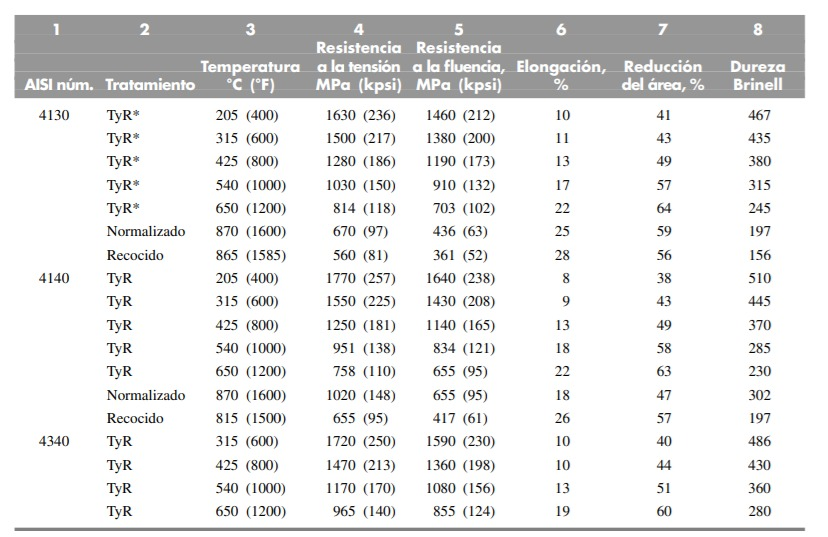

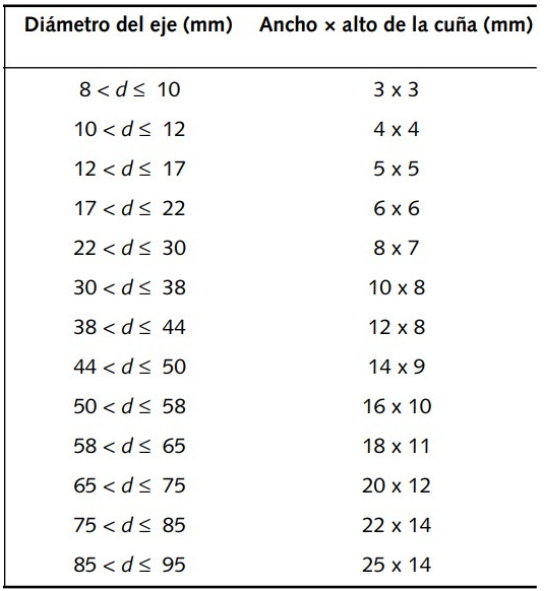



vectorTiempo=BielaManivela.T;
ExtremoEjeFy=-EjeManivela.Fx;
ExtremoEjeFz=EjeManivela.Fz;
ExtremoEjeFx=EjeManivela.Fy;
EjeTorqueMz=EjeManivela.Mz/1000;
EjeTorqueMx=EjeManivela.My/1000;
EjeTorqueMy=-EjeManivela.Mx/1000;
ExtremoBielaFy=BielaManivela.Fz;
ExtremoBielaFz=-BielaManivela.Fy;
ExtremoBielaFx=BielaManivela.Fx;



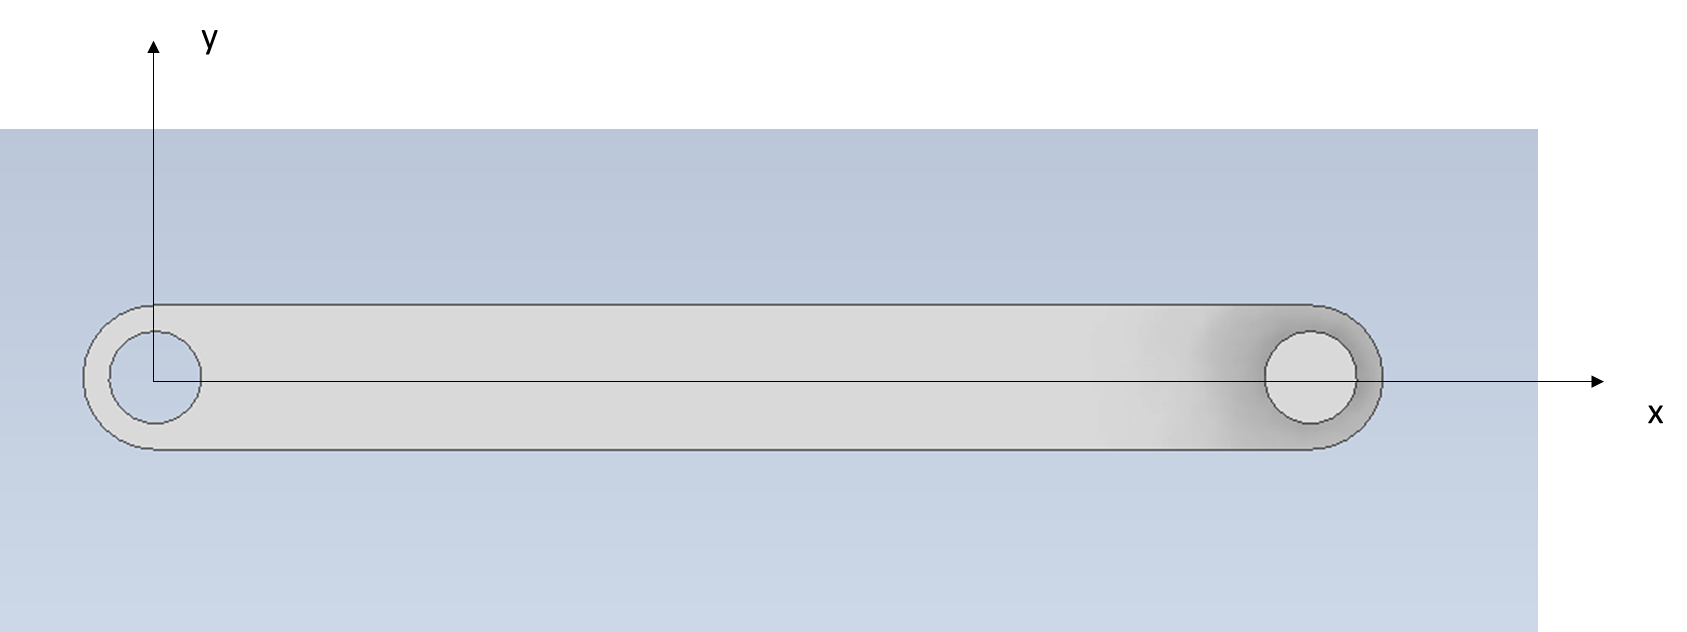

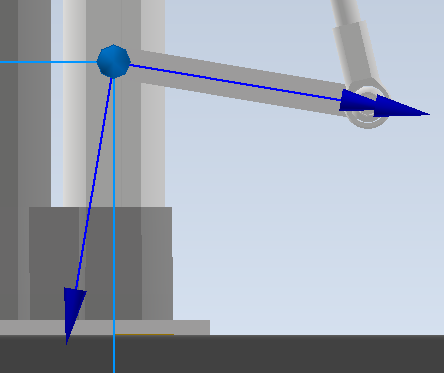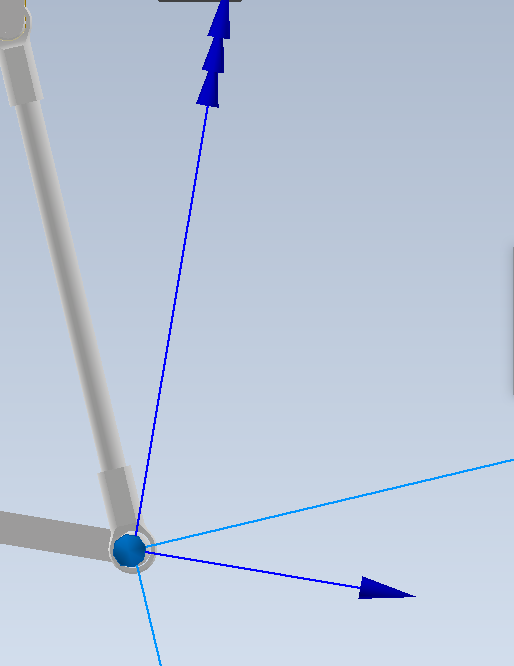

difFx=ExtremoBielaFx+ExtremoEjeFx;
difFy=ExtremoBielaFy+ExtremoEjeFy;
difFz=ExtremoEjeFz+ExtremoBielaFz;


## Análisis unión biela-manivela

ExtremoBielaFy

ExtremoBielaFz

ExtremoBielaFx

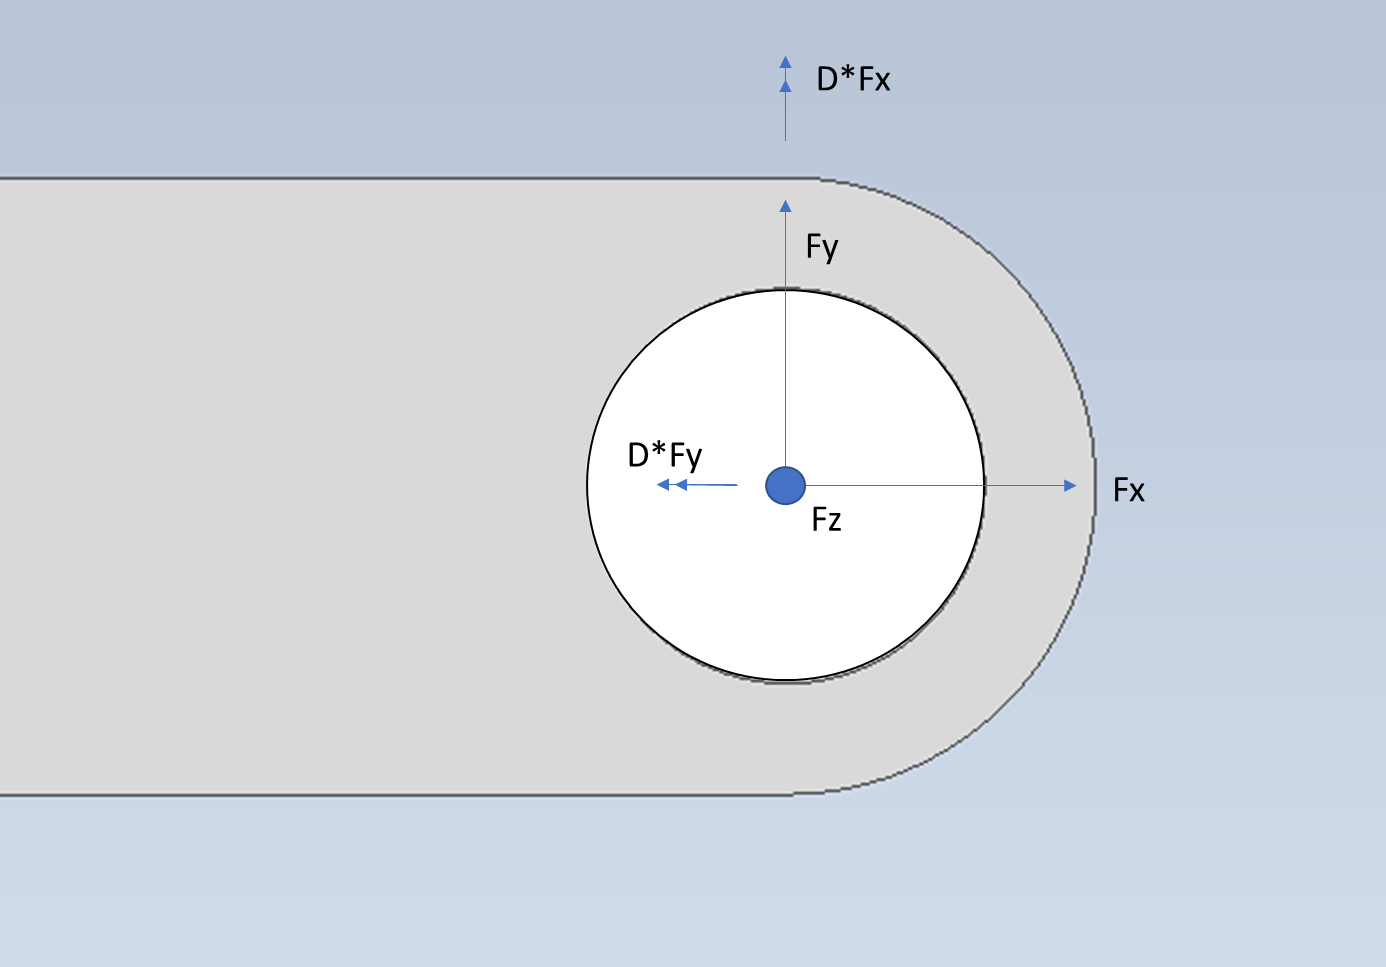

h_bm=0.017;
D_bm=0.0254;

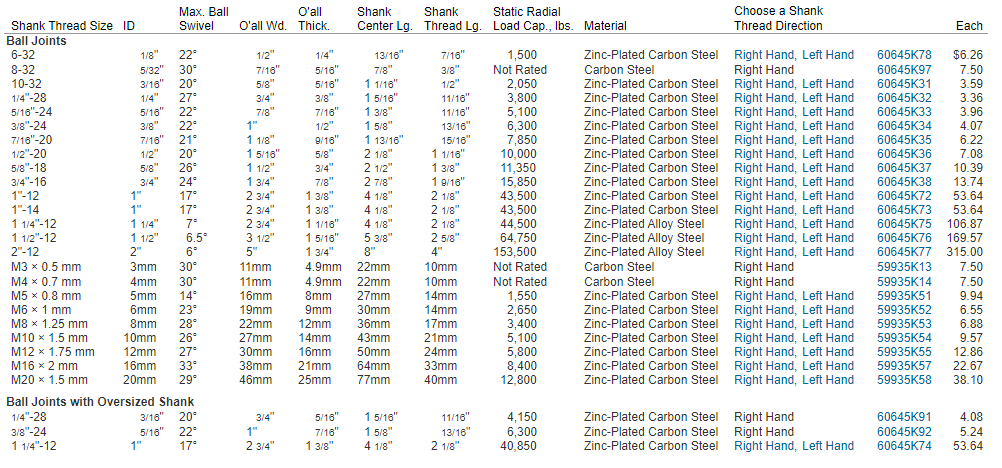

https://www.mcmaster.com/ball-joints/internally-threaded-ball-joint-rod-ends/

I=pi*D_bm^4/64;
A=pi*D_bm^2/4;
My=h_bm*ExtremoBielaFx;
Mx=h_bm*ExtremoBielaFy;
MT=sqrt(My.^2+Mx.^2);

Sigma_t=MT*0.5*D_bm/I;
Sigma_c=-MT*0.5*D_bm/I;
Sigma_normal=ExtremoBielaFz/A;

Sigma_t_Total=(Sigma_normal+Sigma_t);
Sigma_c_Total=(Sigma_normal+Sigma_c);



### Fatiga

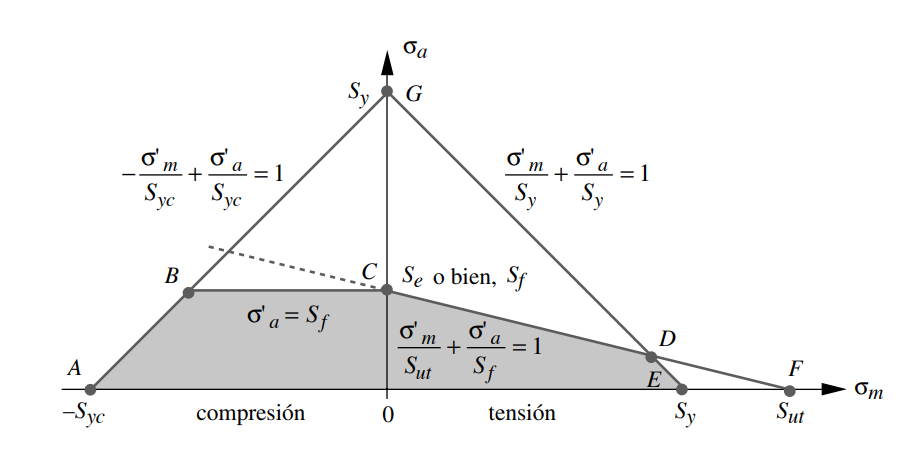

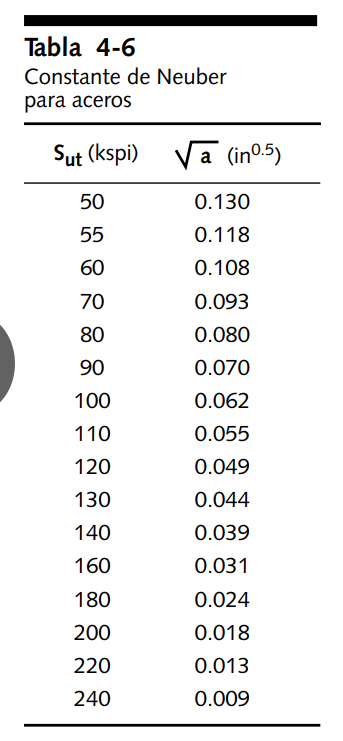

kt=2;
neuberF=0.07; %Corregir neuber
neuberT=0.055;
radioMuesca=0.1; %inches
qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));

KfSold=1+qFlexion*(kt-1);
KfsmSold=1+qTorsion*(kt-1);



mega=1000000;

sigmaAc=KfSold*0.5.*abs(max(Sigma_c_Total)-min(Sigma_c_Total))/mega;   %esfuerzo alternante
sigmaMc=KfSold*0.5.*abs(max(Sigma_c_Total)+min(Sigma_c_Total))/mega;   %esfuerzo medio

sigmaAt=KfSold*0.5.*abs(max(Sigma_t_Total)-min(Sigma_t_Total))/mega;   %esfuerzo alternante
sigmaMt=KfSold*0.5.*abs(max(Sigma_t_Total)+min(Sigma_t_Total))/mega;

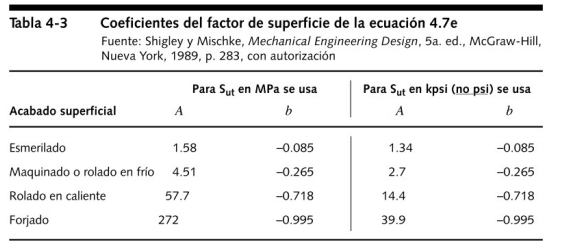

#### Factores de corrección


Fsup=4.51*(Sut)^(-0.265);
Fcar=1; %flexion =1
Ftem=1;

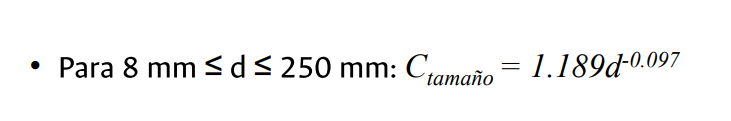

Ctam=1.189*(D_bm*1000)^(-0.097);
Ccon=0.814; % 99%
if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end

Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon;


#### Diagrama de Goodman modificado

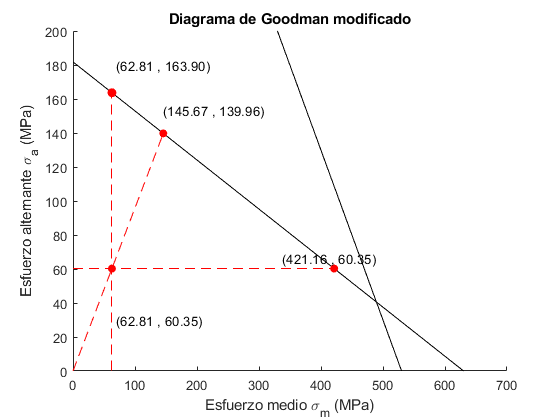

FS1 = 2.7159

FS2 = 2.3192

FS3 = 6.7053

FS_union_biela_t = 2.3192

FS_union_biela_t=diagramaGoodman(sigmaAt,sigmaMt,Sut,Sy,Se,true)

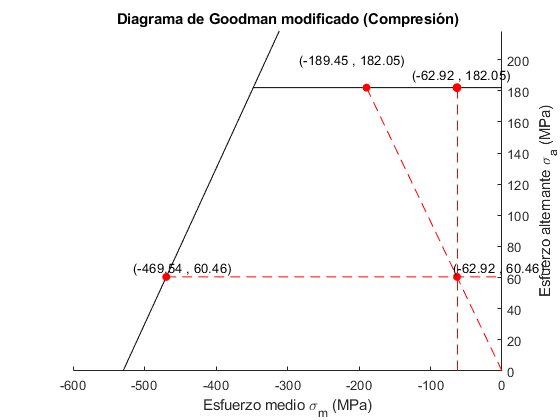

FS1 = 3.0109

FS2 = 3.0109

FS3 = 7.4623

FS_union_biela_c = 3.0109


FS_union_biela_c=diagramaGoodman(sigmaAc,sigmaMc,Sut,Sy,Se,false)

## Análisis unión eje-manivela

### Análisis por extremo

A_seccion=0.5*b_manivela*(D_manivela-d_eje);
J=pi/32*(D_manivela^2-d_eje^2);
I=pi/64*(D_manivela^2-d_eje^2);
r_externo=0.5*D_manivela;

Kt=1.8;

%NPI kts

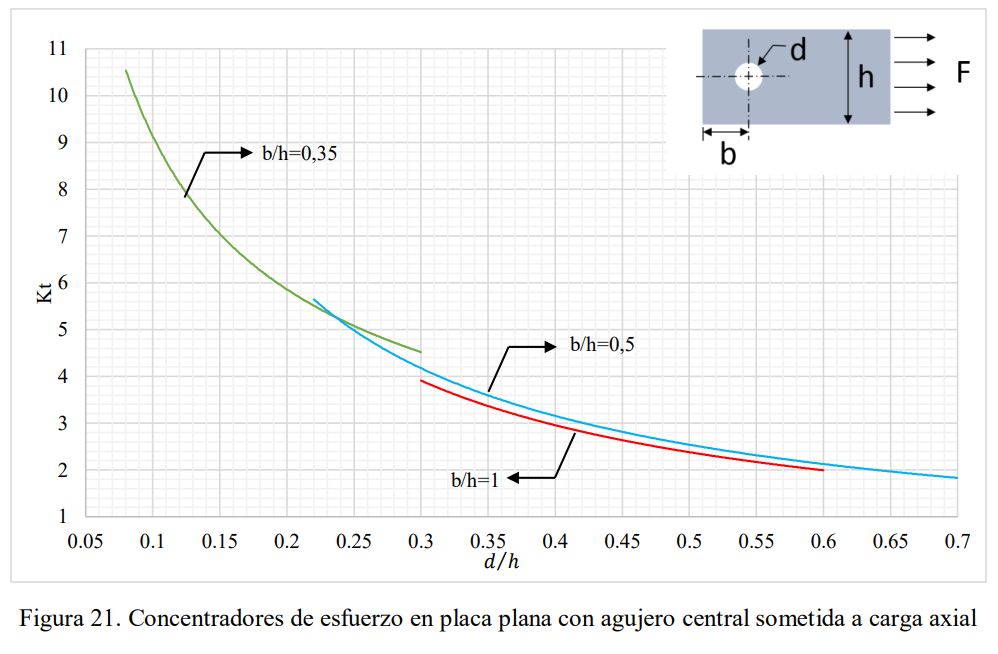

radioMuesca=0.1; %inches
qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));
Kf=1+qFlexion*(kt-1);
Kfsm=1+qTorsion*(kt-1);

Sigma_Fx=ExtremoEjeFx/A_seccion;  %Carga axial:Siempre -i
Sigma_Mz=-EjeTorqueMz*r_externo/I; %Momento flector: +y->-i,-y->i
sigma_My=EjeTorqueMy*r_externo/I; %Momento flector: +z->i,-z->-i

tau_Vy=ExtremoEjeFy/A_seccion; %Carga cortante en j
tau_Vz=ExtremoEjeFz/A_seccion; %Carga cortante en k
tau_Mx=EjeTorqueMx*r_externo/J; %Momento cortante:  +y->+k,-y->-k

Sigma_total=Sigma_Fx+Sigma_Mz+sigma_My;
tau_total=sqrt(tau_Vy.^2+(tau_Vz+tau_Mx).^2);

Sigma_Alternante=0.5*(max(Sigma_total)-min(Sigma_total));
Sigma_Medio=0.5*(max(Sigma_total)+min(Sigma_total));
Tau_Alternante=0.5*(max(tau_total)-min(tau_total));
Tau_Medio=0.5*(max(tau_total)+min(tau_total));

sigmaA=sqrt((Kf*Sigma_Alternante).^2+3*(Kfsm*Tau_Alternante).^2)/mega;
sigmaM=sqrt((Kf*Sigma_Medio).^2+3*(Kfsm*Tau_Medio).^2)/mega;


#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=0.7; %flexion =1
Ftem=1;

A_95=0.05*A_seccion*0.5;
d_eq=sqrt(A_95/0.0766);

Ctam=1.189*(d_eq*1000)^(-0.097);

Ccon=0.897;

if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon;


#### Diagrama de Goodman

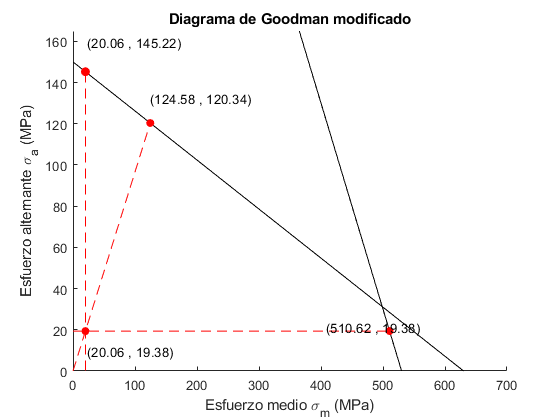

FS1 = 7.4939

FS2 = 6.2098

FS3 = 25.4529

FS_cortante_eje_extremo = 6.2098

FS_cortante_eje_extremo=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

### Análisis por cuña

A_seccion=0.5*b_manivela*(D_manivela-d_eje);
J=pi/32*(D_manivela^2-d_eje^2);
I=pi/64*(D_manivela^2-d_eje^2);
r_externo=0.5*D_manivela;

Kt=2;
Kts=2.75;

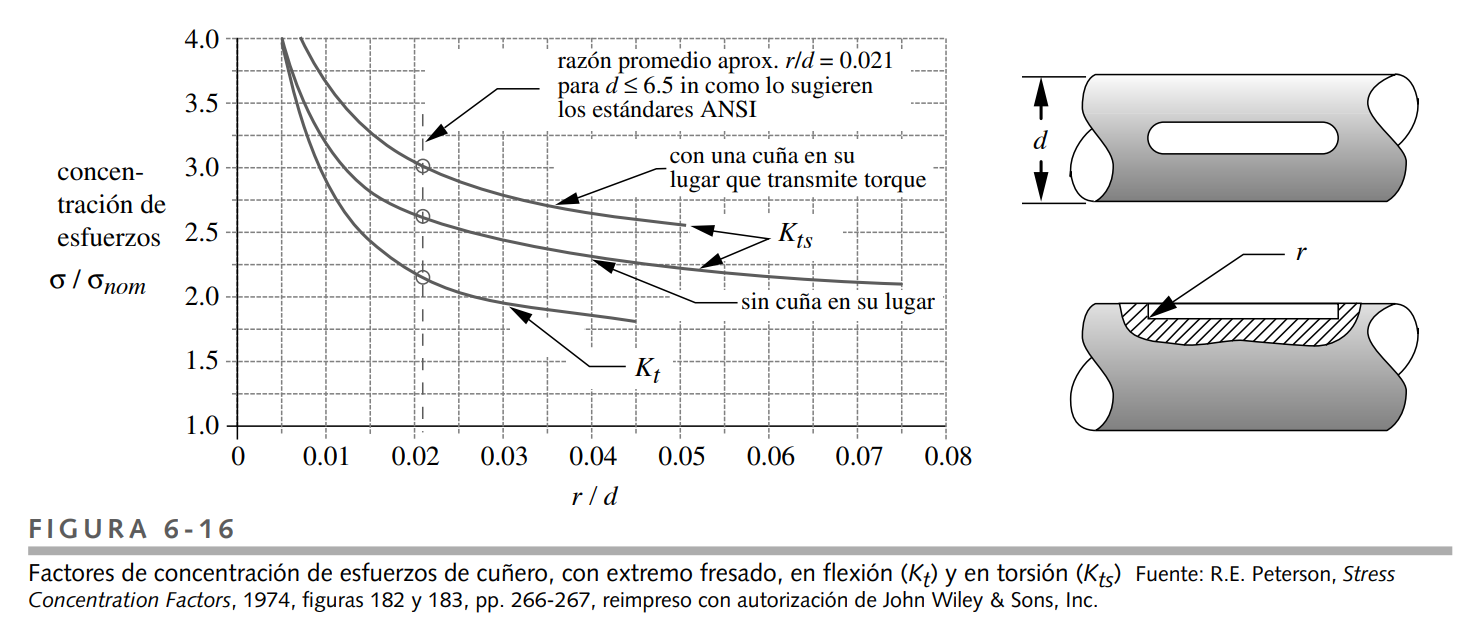

radioMuesca=0.1; %inches
qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));
Kf=1+qFlexion*(kt-1);
Kfsm=1+qTorsion*(Kts-1);

Sigma_Fx=ExtremoEjeFx/A_seccion;  %Carga axial:Siempre -i
Sigma_Mz=-EjeTorqueMz*r_externo/I; %Momento flector: +y->-i,-y->i
sigma_My=EjeTorqueMy*r_externo/I; %Momento flector: +z->i,-z->-i

tau_Vy=ExtremoEjeFy/A_seccion; %Carga cortante en j
tau_Vz=ExtremoEjeFz/A_seccion; %Carga cortante en k
tau_Mx=EjeTorqueMx*r_externo/J; %Momento cortante:  +y->+k,-y->-k

Sigma_total=Sigma_Fx+Sigma_Mz+sigma_My;
tau_total=sqrt(tau_Vy.^2+(tau_Vz+tau_Mx).^2);

Sigma_Alternante=0.5*(max(Sigma_total)-min(Sigma_total));
Sigma_Medio=0.5*(max(Sigma_total)+min(Sigma_total));
Tau_Alternante=0.5*(max(tau_total)-min(tau_total));
Tau_Medio=0.5*(max(tau_total)+min(tau_total));

sigmaA=sqrt((Kf*Sigma_Alternante).^2+3*(Kfsm*Tau_Alternante).^2)/mega;
sigmaM=sqrt((Kf*Sigma_Medio).^2+3*(Kfsm*Tau_Medio).^2)/mega;


#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=0.7; %flexion =1
Ftem=1;

A_95=0.05*A_seccion*0.5;
d_eq=sqrt(A_95/0.0766);

Ctam=1.189*(d_eq*1000)^(-0.097);

Ccon=0.897;

if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon;


#### Diagrama de Goodman

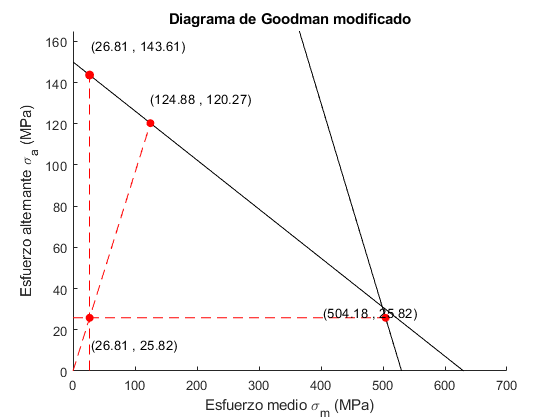

FS1 = 5.5624

FS2 = 4.6581

FS3 = 18.8065

FS_cortante_eje_cuna = 4.6581

FS_cortante_eje_cuna=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

## Análisis cuña-cuñero Cortante






Sut=630  

Sut = 630

Sy=530

Sy = 530


%parametros cuña


A_t=W*L;

r_eje=0.5*d_eje;
Torque=EjeTorqueMz;
r_cuna=0.03*d_eje;


Carga_cortante=Torque/r_eje;
tau_V=Carga_cortante/A_t;

sigmaA=sqrt(3)*0.5*(max(tau_V)-min(tau_V))/mega;
sigmaM=sqrt(3)*0.5*(max(tau_V)+min(tau_V))/mega;



#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=1; %flexion =1
Ftem=1;
Ccon=0.897;


A_95=0.05*L*W;
d_eq=sqrt(A_95/0.0766);
Ctam=1.189*(d_eq*1000)^(-0.097);

if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon;


#### Diagrama de Goodman

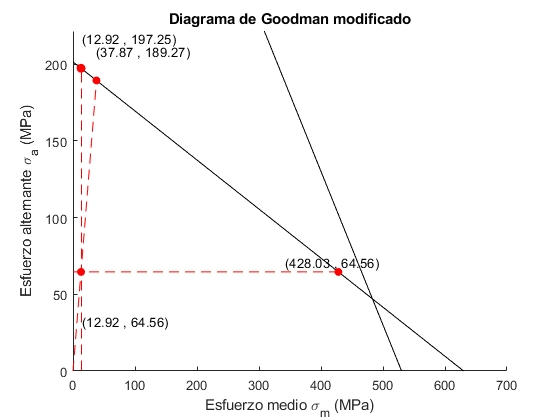

FS1 = 3.0553

FS2 = 2.9317

FS3 = 33.1317

FS_cortante_cuna = 2.9317

FS_cortante_cuna=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

## Análisis cuña-cuñero aplastamiento


Sec_ap=5.382*0.001;
A_sigma=Sec_ap*L;
sigma_V=Carga_cortante/A_sigma;
sigma_V1=sigma_V;
sigma_V1(sigma_V1<0)=[];
sigma_V2=sigma_V;
sigma_V2(sigma_V2>0)=[];
sigma_V2=abs(sigma_V2);

%sigmaA=0.5*(max(sigma_V)-min(sigma_V))/mega
%sigmaM=0.5*(max(sigma_V)+min(sigma_V))/mega

sigmaA1=0.5*max(sigma_V1)/mega;
sigmaM1=0.5*max(sigma_V1)/mega;

sigmaA2=0.5*max(sigma_V2)/mega;
sigmaM2=0.5*max(sigma_V2)/mega;



#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=0.7; %flexion =1
Ftem=1;
Ccon=0.897;

A_95=0.05* H*W;
d_eq=sqrt(A_95/0.0766);
Ctam=1.189*(d_eq*1000)^(-0.097);

SeSC=0.5*Sut;
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon;


#### Diagrama de Goodman

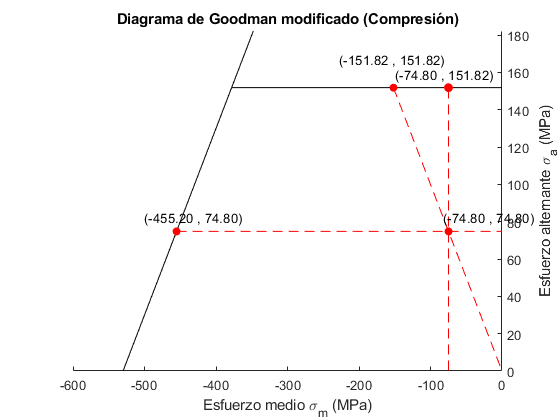

FS1 = 2.0296

FS2 = 2.0296

FS3 = 6.0853

FS_aplastamiento_cuna_1 = 2.0296

%FS_aplastamiento_cuna_1=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,false)

FS_aplastamiento_cuna_1=diagramaGoodman(sigmaA1,sigmaM1,Sut,Sy,Se,false)

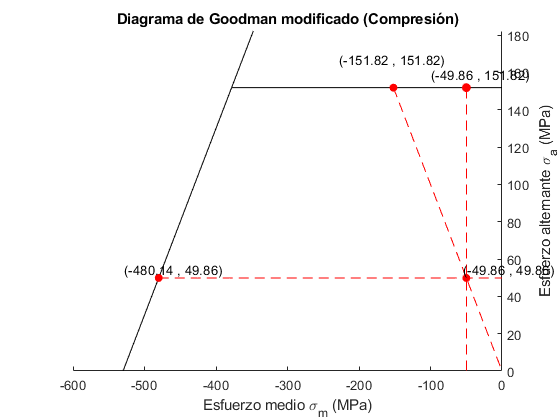

FS1 = 3.0451

FS2 = 3.0451

FS3 = 9.6304

FS_aplastamiento_cuna_2 = 3.0451


FS_aplastamiento_cuna_2=diagramaGoodman(sigmaA2,sigmaM2,Sut,Sy,Se,false)

function FSMin=diagramaGoodman(EsigmaA,EsigmaM,ESut,ESy,ESe,tension)
syms x1 x2 x3 x4 x5

if(tension)
sigmaA=EsigmaA;
sigmaM=EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;
Fq2=Se-x5./Sut.*Se==sigmaA;

FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSy2=double(solve(Fq2,x5));

if(FSy2<FSy)
    FSy=FSy2;
end




figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(0.8*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")
FS1=goodManM(sigmaM)/sigmaA
FS2=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]);

else
    
    
sigmaA=EsigmaA;
sigmaM=-EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy+x;
goodManM=@(x)  Se;
lineaC=@(x)     sigmaA.*x./sigmaM;
Fr=sigmaA.*x1/sigmaM==Se;
Fq= Sy+x2==sigmaA;
Fc2=Se==Sy+x3;
FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSn=double(solve(Fc2,x3));
figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[-Sy 0],"k")
fplot(goodManM,[FSn 0],"k")
fplot(lineaC,[FSm 0],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[FSy 0],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,1.1*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(2*sigmaM,1.05*Se,sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(1.5*FSm,1.1*Se,sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(1.1*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.2])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado (Compresión)")
ax=gca;
ax.YAxisLocation = 'right';
FS1=Se/sigmaA
FS2=sqrt(FSm^2+Se^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]); 
end
end